
[x]=importdata('listx.txt');

[y]=importdata('listy.txt');

[z]=importdata('listz.txt');

%[LATGRID,LONGRID]=meshgrid(latGRID,lonGRID)d
%}
% Punto inicial 39.020594, -0.211071
% Punto final 38.944588, -0.129491

% Dividimos la lat/lon inicial hasta la lat/lon final de 20*n en 20*n
% metros.
y1 = 38.944588:(0.00018*2):39.020594; 
x1= -0.211071:(0.00023*2):-0.129491;

[X1,Y1] = meshgrid(x1,y1);


[X1,Y1] = meshgrid(x1,y1);

writematrix(X1,"fixedx.txt",'Delimiter',',') 
writematrix(Y1,"fixedy.txt",'Delimiter',',') 

Z_corrector= griddata(x,y,z,X1,Y1,'v4');

Z_corrector = max(0,min(100,Z_corrector))

Z_corrector =          0    1.2257    2.4820    3.7606    5.0572    6.3685    7.6919    9.0251   10.3663   11.7137   13.0659   14.4212   15.7784   17.1361   18.4932   19.8484   21.2006   22.5488   23.8918   25.2287   26.5584   27.8799   29.1924   30.4947   31.7861   33.0655   34.3322   35.5852   36.8237   38.0467   39.2536   40.4433   41.6153   42.7685   43.9023   45.0159   46.1086   47.1796   48.2281   49.2536   50.2553   51.2327   52.1849   53.1115   54.0119   54.8854   55.7316   56.5500   57.3400   58.1013
    0.6407    1.8691    3.1289    4.4118    5.7131    7.0292    8.3577    9.6961   11.0427   12.3955   13.7532   15.1141   16.4770   17.8404   19.2033   20.5643   21.9224   23.2764   24.6254   25.9681   27.3037   28.6312   29.9495   31.2578   32.5550   33.8402   35.1127   36.3714   37.6155   38.8441   40.0563   41.2515   42.4286   43.5870   44.7257   45.8441   46.9414   48.0169   49.0697   50.0992   51.1048   52.0857   53.0413   53.9710   54.8742   55.7503   56.5988   57.4192   58


max(max(Z_corrector))

ans = 100

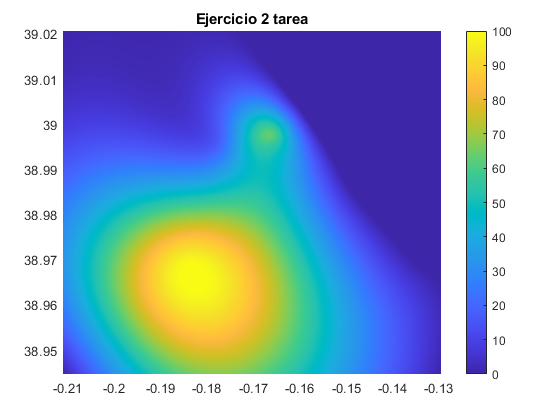


 pcolor(X1,Y1,Z_corrector), shading interp, colorbar
% plot(Z_corrector)
title('Ejercicio 2 tarea')


% figure, [C,h]=contour(X1,Y1,LDEN_corrector, 30); clabel(C,h),colorbar
% title('Curvas de nivel tarea 2')
writematrix(Z_corrector,'result.txt','Delimiter',',')  
